# ベクトルの線形従属・独立(2)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
v1=[1;1;0]

v1 =      1
     1
     0


v2=[-1;2;1]

v2 =     -1
     2
     1


v3=[1;4;1]

v3 =      1
     4
     1


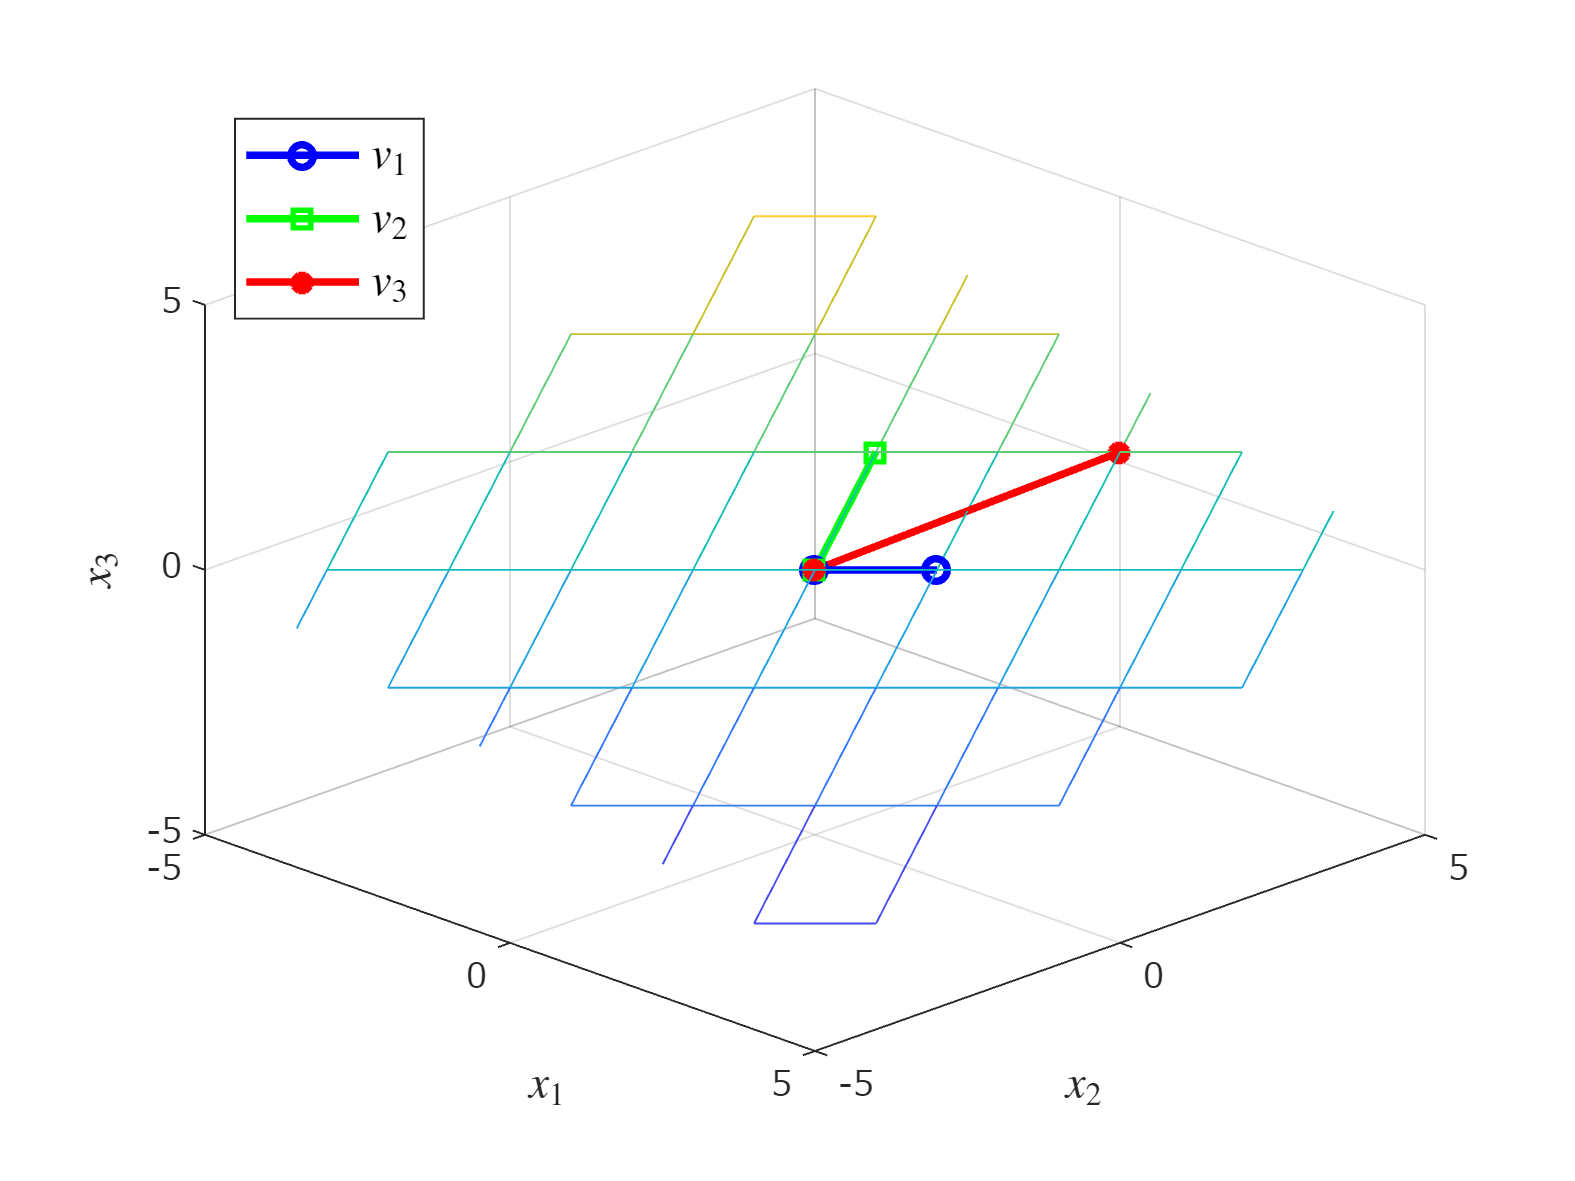

X=zeros(9,9);
Y=zeros(9,9);
Z=zeros(9,9);
for n1=-4:4
    for n2=-4:4
        tmpV=n1*v1+n2*v2;
        X(n1+5,n2+5)=tmpV(1);
        Y(n1+5,n2+5)=tmpV(2);
        Z(n1+5,n2+5)=tmpV(3);

    end
end
figure;hold on;
grid on;
set(gca,'fontname','メイリオ');
hv(1)=plot3([0 v1(1)],[0 v1(2)],[0 v1(3)],'bo-','LineWidth',2);
hv(2)=plot3([0 v2(1)],[0 v2(2)],[0 v2(3)],'gs-','LineWidth',2);
hv(3)=plot3([0 v3(1)],[0 v3(2)],[0 v3(3)],'r*-','LineWidth',2);
mesh(X,Y,Z,'FaceAlpha',0);
xlabel('$x_1$','Interpreter','latex','FontSize',12);
ylabel('$x_2$','Interpreter','latex','FontSize',12);
zlabel('$x_3$','Interpreter','latex','FontSize',12);
xlim([-5 5]);ylim([-5 5]);zlim([-5 5]);
legend(hv,{'$v_1$','$v_2$','$v_3$'},'Interpreter','latex','Location','northwest', ...
    'FontSize',12)

for n1=1:120
    view([3*n1+45,30]);
    pause(0.01)
end

v=[[1;1;0] [-1;2;1] [0;-1;3]]

v =      1    -1     0
     1     2    -1
     0     1     3


X=zeros(9,9);
Y=zeros(9,9);
Z=zeros(9,9);
for n1=-4:4
    for n2=-4:4
        tmpV=n1*v(:,1)+n2*v(:,2);
        X(n1+5,n2+5)=tmpV(1);
        Y(n1+5,n2+5)=tmpV(2);
        Z(n1+5,n2+5)=tmpV(3);

    end
end

figure;hold on;
grid on;
set(gca,'fontname','メイリオ');
hv(1)=plot3([0 v(1,1)],[0 v(2,1)],[0 v(3,1)],'bo-','LineWidth',2);
hv(2)=plot3([0 v(1,2)],[0 v(2,2)],[0 v(3,2)],'gs-','LineWidth',2);
hv(3)=plot3([0 v(1,3)],[0 v(2,3)],[0 v(3,3)],'r*-','LineWidth',2);
mesh(X,Y,Z,'FaceAlpha',0);view([45,30]);
xlabel('$x_1$','Interpreter','latex','FontSize',12);
ylabel('$x_2$','Interpreter','latex','FontSize',12);
zlabel('$x_3$','Interpreter','latex','FontSize',12);
xlim([-5 5]);ylim([-5 5]);zlim([-5 5]);
legend(hv,{'$v_1$','$v_2$','$v_3$'},'Interpreter','latex','Location','northwest', ...
    'FontSize',12)

exportgraphics(gcf,'fig_linearDependancySample02.pdf');
for n1=1:120
    view([3*n1+45,30]);
    pause(0.01)
end